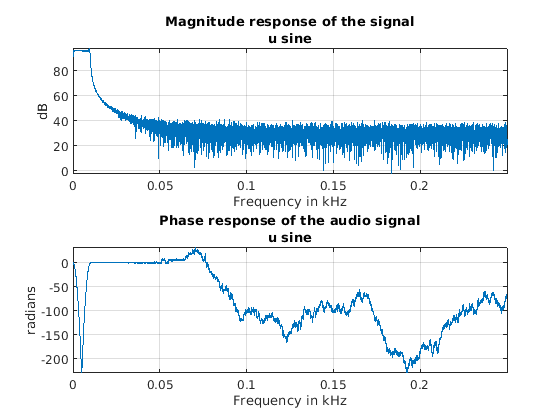

clear;
load thruster_data.mat;
% Define the sampling frequency of the input signal
Fs = 1 / Ts; % in Hz

% shift data to simulate initial conditions zero
% u_sine is constant in the first 40 sampling times,
% so we can study the steady-state value of the system before the
% experiment
u_shift = 1750;
y_shift = mean(data_sine.y(1:40));
data_sine_shifted = shiftData(data_sine, u_shift, y_shift);

% remove first value because it is not helpful
data_square = iddata(data_square.y(2:end), data_square.u(2:end), Ts);
data_square_shifted = shiftData(data_square, u_shift, y_shift);

spectralAnalysis(data_sine_shifted.u, Fs, 'u sine')

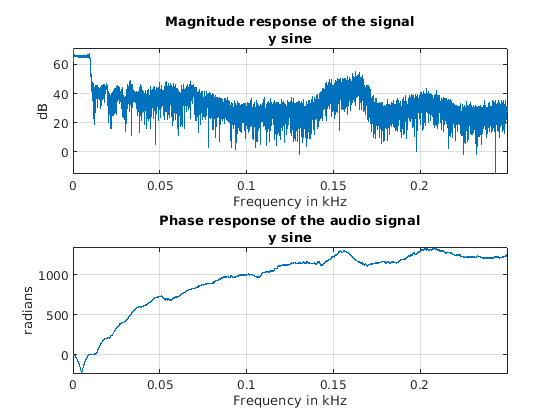

spectralAnalysis(data_sine_shifted.y, Fs, 'y sine')

Design lowpass filter for sine data. We observe that highest frequency in input signal is 10 Hz. So we choose cutoff frequency just slightly higher

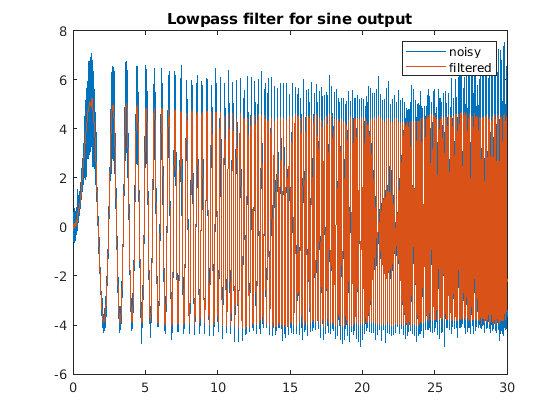

cutoff_freq = 11;


% Compute the normalized cutoff frequency (between 0 and 1)
% is factor two correct like this?
normalized_cutoff_freq = 2 * cutoff_freq / Fs;

y_sine_filtered = lowpass(data_sine_shifted.y, normalized_cutoff_freq, Fs);

figure
plot(time, data_sine_shifted.y, time, y_sine_filtered);
legend('noisy', 'filtered');
title('Lowpass filter for sine output')


% visual inspection: filtered signal doesn't seem distorted, can be used
% for entire time length!

Do the same process for the square chirp signal. 

We can see that the square wave also has a frequency of 10 at the end. However this means that the "true" signal without noise has considerable higher frequencies in the spectral domain. 

It might be hard to tell apart high frequencies from signal and from noise.

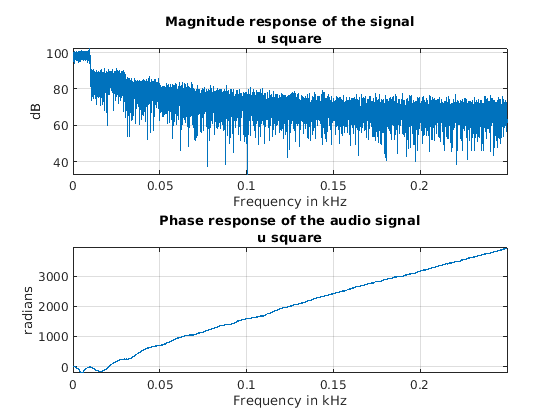

spectralAnalysis(data_square_shifted.u, Fs, 'u square')

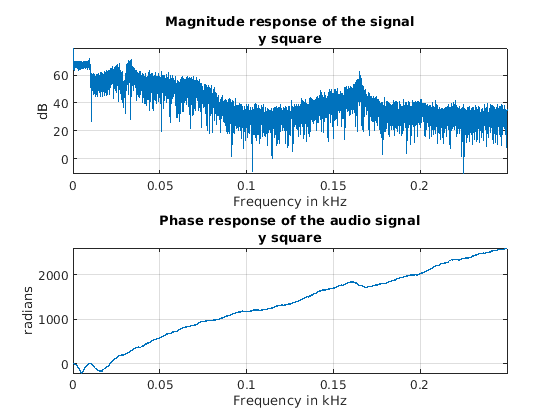

spectralAnalysis(data_square_shifted.y, Fs, 'y square')

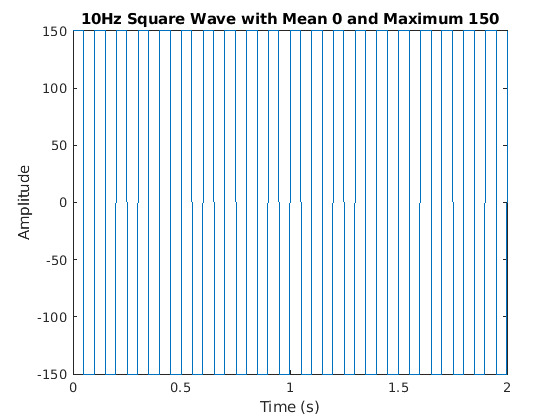

% Set the frequency and duration of the square wave
% Set the frequency and duration of the square wave
freq = 10;       % Hz
duration = 2;    % seconds

% Set the amplitude and DC offset of the square wave
amplitude = 150;
DC_offset = 0;

% Create the time vector with a small step size
t = 0:Ts:duration;

% Create the square wave using the 'square' function
u_test = amplitude*square(2*pi*freq*t) + DC_offset;

% Plot the square wave
figure
plot(t, u_test)
xlabel('Time (s)')
ylabel('Amplitude')
title('10Hz Square Wave with Mean 0 and Maximum 150')

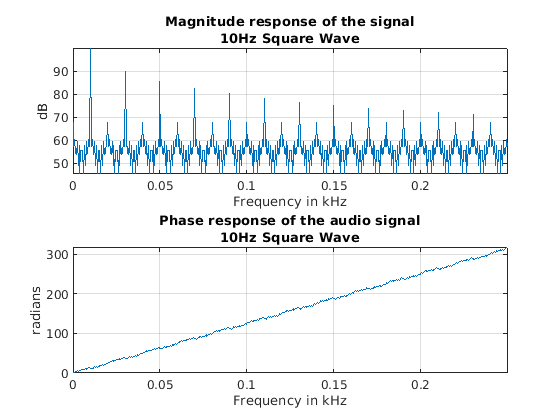

spectralAnalysis(u_test, Fs, '10Hz Square Wave')

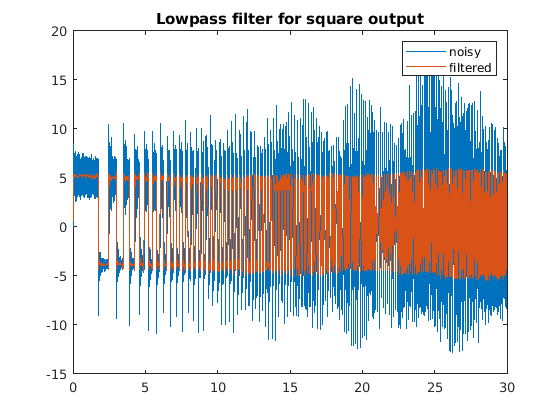

% by trial and error
cutoff_freq = 150;
normalized_cutoff_freq = 2 * cutoff_freq / Fs;

y_square_filtered = lowpass(data_square_shifted.y, normalized_cutoff_freq, Fs);

figure
time_plot = 0:Ts:(length(data_square_shifted.y) - 1)*Ts;
plot(time_plot, data_square_shifted.y, time_plot, y_square_filtered);
legend('noisy', 'filtered');
title('Lowpass filter for square output')

% visual inspection: filtered signal doesn't seem distorted, can be used
% for entire time length!

Since we fear that frequencies of true signal and of noise are overlapping at the end, we cut off the end of the data in the time domain

cutoff_seconds = 15;
cutoff_indices = 1:(cutoff_seconds / Ts)

cutoff_indices =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y_square_filtered_cutoff = y_square_filtered(cutoff_indices);
u_square_cutoff = data_square_shifted.u(cutoff_indices);
% also make this cutoff for the unfiltered data
data_square_shifted = iddata(data_square_shifted.y(cutoff_indices), data_square_shifted.u(cutoff_indices), Ts);

% create a new .mat container with the preprocessed data
s = struct;
s.data_sine = iddata(y_sine_filtered, data_sine_shifted.u, Ts);
s.data_sine_unfiltered = data_sine_shifted;
s.data_square = iddata(y_square_filtered_cutoff, u_square_cutoff, Ts);
s.data_square_unfiltered = data_square_shifted;
% set plot information
% Create cell array of field names
fields = fieldnames(s);
% Iterate through fields and modify OutputName property
for i = 1:numel(fields)
    s.(fields{i}).OutputName = 'Force';
    s.(fields{i}).OutputUnit = 'lb';
    s.(fields{i}).TimeUnit   = 'seconds';
end

s.Ts = Ts;
s.time_sine = 0:Ts:(length(u_sine)-1)*Ts;
s.time_square = 0:Ts:(length(u_square_cutoff) - 1)*Ts;
% store offset as well to be able to re-transfer when using model for
% prediction
s.u_shift = u_shift;
s.y_shift = y_shift;
save('processed_thruster_data.mat', '-struct', 's')

% check processed data
tmp = load('processed_thruster_data.mat')

tmp = struct with fields:
                 data_sine: [15001x1x1 iddata]
      data_sine_unfiltered: [15001x1x1 iddata]
               data_square: [7500x1x1 iddata]
    data_square_unfiltered: [7500x1x1 iddata]
                        Ts: 0.0020
                 time_sine: [0 0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 0.0620 ... ]
               time_square: [0 0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0260 0.0280 0.0300 0.0320 0.0340 0.0360 0.0380 0.0400 0.0420 0.0440 0.0460 0.0480 0.0500 0.0520 0.0540 0.0560 0.0580 0.0600 0.0620 ... ]
                   u_shift: 1750
                   y_shift: 5.0950


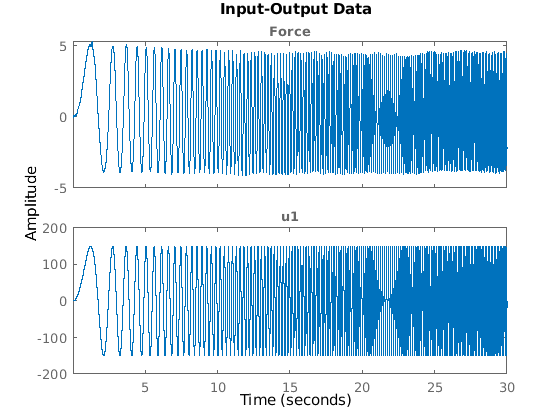

idplot(tmp.data_sine)

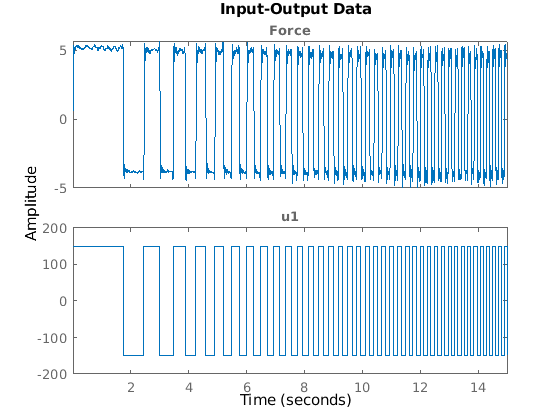

idplot(tmp.data_square)

function dataNew = shiftData(data, u_shift, y_shift)
    % assuming system was in steady state before
    u_new = data.u - u_shift;
    % 5 is read off because plots suggest that this was the inital value
    % without noise in both cases
    y_new = data.y - y_shift;
    dataNew = iddata(y_new, u_new, data.Ts);
end

function spectralAnalysis(y, Fs, signalName)
    NFFT = length(y);
    % helperFrequencyAnalysisPlot1 wants pair NFFT
    if mod(NFFT, 2) == 1
        y = y(1:end-1);
        NFFT = NFFT - 1;
    end
    Y = fft(y, NFFT);
    F = ((0:1/NFFT:1-1/NFFT)*Fs).';
    magnitudeY = abs(Y);        % Magnitude of the FFT
    phaseY = unwrap(angle(Y));  % Phase of the FFT

    helperFrequencyAnalysisPlot1(F,magnitudeY,phaseY,NFFT, signalName, signalName)
end

function helperFrequencyAnalysisPlot1(F,Ymag,Yangle,NFFT,ttlMag,ttlPhase)
% Plot helper function for the FrequencyAnalysisExample

% Copyright 2012 The MathWorks, Inc.

figure
subplot(2,1,1)
plot(F(1:NFFT/2)/1e3,20*log10(Ymag(1:NFFT/2)));
if nargin > 4 && ~isempty(ttlMag)
  tstr = {'Magnitude response of the signal',ttlMag};
else
  tstr = {'Magnitude response of the signal'};
end
title(tstr)
xlabel('Frequency in kHz')
ylabel('dB')
grid on;
axis tight 
subplot(2,1,2)
plot(F(1:NFFT/2)/1e3,Yangle(1:NFFT/2));
if nargin > 5
  tstr = {'Phase response of the audio signal',ttlPhase};
else  
  tstr = {'Phase response of the audio signal'};
end
title(tstr)
xlabel('Frequency in kHz')
ylabel('radians')
grid on;
axis tight
end